Image = imread('HotCrossBuns.jpg');
[x, y] = createMask2(Image);
W = x((160:230), (162:200));
Map = zeros(71,500);
Map(1:71, 1:39) = W;
Map(20:21, :) = 1;
Map(28:29, :) = 1;
Map(36:37, :) = 1;
Map(44:45, :) = 1;
Map(52:53, :) = 1;
BackGroundNote = Map(:, 40:51);

Ball = readmatrix('ball.csv');
Ball = logical(Ball(1:8,1:12));


imshow(BackGroundNote)

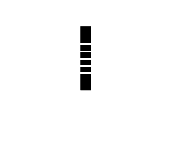

E1  = LineNoteMap(21, bgn1);

C1  = LineNoteMap(29, bgn1);
A1  = LineNoteMap(37, bgn1);
F1  = LineNoteMap(45, bgn1);
FL1 = LineNoteMap(17, bgn1);
DL1 = LineNoteMap(25, bgn1);
BL1 = LineNoteMap(33, bgn1);
GL1 = LineNoteMap(41, bgn1);
EL1 = LineNoteMap(49, bgn1);

Image = imread('HotCrossBuns.jpg');
[x, y] = createMask2(Image);
imshow(x)


Line = [W BL1 A1 GL1 BL1 A1 GL1];

AA = Getter(Line)



Yrange = 71;
Xrange = 12;
sz = size(Line);
caught = [];
for row = 1 : (sz(1) - Yrange - 1)
    for col = 1 : (sz(2) - Xrange - 1)
        Suspect = Line(row:(row + Yrange - 1), col:(col + Xrange - 1));
        %Getter(Suspect)
        caught = [caught Getter(Suspect)];
        
    end
end
caught

bgn1 = [
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
1	1	1	1	1	1	1	1	1	1	1	1;
1	1	1	1	1	1	1	1	1	1	1	1;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
1	1	1	1	1	1	1	1	1	1	1	1;
1	1	1	1	1	1	1	1	1	1	1	1;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
1	1	1	1	1	1	1	1	1	1	1	1;
1	1	1	1	1	1	1	1	1	1	1	1;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
1	1	1	1	1	1	1	1	1	1	1	1;
1	1	1	1	1	1	1	1	1	1	1	1;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
1	1	1	1	1	1	1	1	1	1	1	1;
1	1	1	1	1	1	1	1	1	1	1	1;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
0	0	0	0	0	0	0	0	0	0	0	0;
];

function [Caught] = Getter(im)
	E.value = NoteMap(21);
	E.name = 'E';       
	C.value = NoteMap(29);
	C.name = 'C';       
	A.value = NoteMap(37);
	A.name = 'A';       
	F.value = NoteMap(45);
	F.name = 'F';
	FL.value = NoteMap(17);
	FL.name = 'FL';
	DL.value = NoteMap(25);
	DL.name = 'DL';
	BL.value = NoteMap(33);
	BL.name = 'BL';
	GL.value = NoteMap(41);
	GL.name = 'GL';
	EL.value = NoteMap(49);
	EL.name = 'EL';
	
	Masks = [E C A F FL DL BL GL EL];
	
	Caught = [];
	Sz = size(im);
	%snd = Sz(2);
    fst = Sz(1);
	for q = 1 : 1
		for Test = Masks
			if (im(:, q:q + 11) & Test.value) == Test.value;
				Caught = [Caught ' ' Test.name];
				%Caught = Test.name;
				%return
			end
        end
	end
end


function [S] = LineNoteMap(NoteBase, BackGroundNote)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
z = NoteBase;
x = NoteBase + 7;
S = S | BackGroundNote;
S(z:x,:) = S(z:x,:) | Ball;
end

function [S] = NoteMap(NoteBase)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
z = NoteBase;
x = NoteBase + 7;
S(z:x,:) = S(z:x,:) | Ball;
end

function [BW,maskedRGBImage] = createMask2(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 17-May-2022
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 0.009;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 0.810;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
